% Step-by-step live script to isolate the eye from a close-up picture of half a face.
% Assumes image filename is provided. Edit 'imgFile' as needed.

% 1) Read image
imgFile = 'frame_0011.png'; % <-- change to your filename
Iorig = imread(imgFile);
I = im2double(Iorig);


% Resize for speed (optional)
scale = 0.7;
I = imresize(I, scale);


% Convert to HSV
hsv = rgb2hsv(I);
H = hsv(:,:,1);
S = hsv(:,:,2);
V = hsv(:,:,3);



V_thresh=0.1

V_thresh = 0.1000

S_thresh=0.1

S_thresh = 0.1000

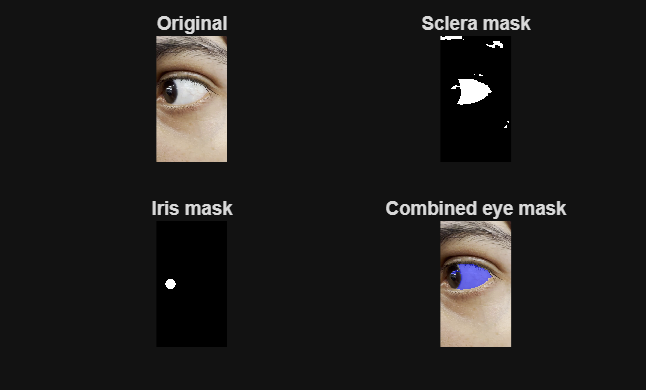


% 1) Sclera detection: bright and low saturation (white-ish)
scleraMask = (V > V_thresh) & (S < S_thresh);
% Show intermediate scleraMask before morphological cleaning
% Clean sclera mask
scleraMask = imopen(scleraMask, strel('disk',3));
scleraMask = imclose(scleraMask, strel('disk',7));
scleraMask = imfill(scleraMask, 'holes');


%
% figure;
%imshow(scleraMask);
%title('Raw Sclera Mask (pre-cleaning)');
%drawnow;





% Combine and refine (sclera + iris)
eyeMask = scleraMask;
eyeMask = bwareafilt(eyeMask,1);   % keep largest connected region (optional)
eyeMask = imclose(eyeMask, strel('disk',5));
eyeMask = imfill(eyeMask, 'holes');

% Display
figure;
subplot(2,2,1), imshow(I), title('Original');
subplot(2,2,2), imshow(scleraMask), title('Sclera mask');
subplot(2,2,3), imshow(irisMask), title('Iris mask');
subplot(2,2,4), imshow(labeloverlay(I, eyeMask)), title('Combined eye mask');